clear all;
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

inital_state=[1 0 0 0 0 0]';
sample_num=10000;center=100;sigma=1;

precession=[0:0.1:2].*pi;

for j=1:length(precession)
    precession_time=precession(j);
    for i=1:sample_num
        distribution=normrnd(center,sigma);
        ham_piover2=sigmay;
        ham_precession=1*sigmaz+1*distribution.*sigmaz^2;
        transverse_polar=ham_evolve(ham_piover2,inital_state,pi/2);
        precess_state=ham_evolve(ham_precession,transverse_polar,precession_time);
        final_state=ham_evolve(ham_piover2,precess_state,pi/2);
        singlestate_population(:,i)=abs(final_state).^2;        
    end
    sample_mean(:,j)=mean(singlestate_population,2);
    cat_population(j)=sample_mean(1,j)+sample_mean(6,j);
end

## Plot

f=figure;hold on;
legend_string="";
for i=1:6
    plot(precession/pi,sample_mean(i,:));
    legend_string(i)=join(['state ',num2str(i)]);
end
legend;
set(gca,'Fontname','Times new roman');

xlabel('Precession time/\pi');

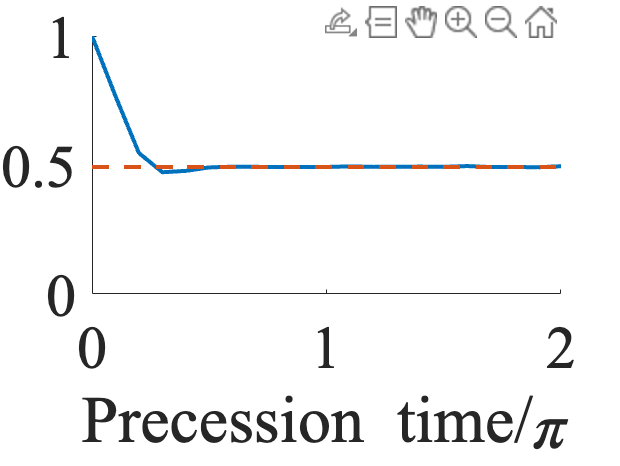

legend;


f=figure;hold on;
l1=plot(precession/pi,cat_population);

set(l1,'linewidth',2)
set(gca,'FontSize',30,'Fontname','Times new roman');
%set(f,'visible','on');
xlabel('Precession time/\pi');
ylim([0 1]);
hold on;

l2=plot([min(precession)/pi,max(precession)/pi],[63/128,63/128],'--');
set(l2,'linewidth',2);

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
